## 1）

## a)


badpixels = zeros(1, 2500);

parfor(i = 1:2500, 5)
    cleani = 1 - bwareaopen(1 - badIm, i);
    badpixels(i) = sum(sum(xor(idealIm, cleani)));
end

x = linspace(1, 2500, 2500);
scatter(x, badpixels, 1, "blue", 'filled')

## b)

The initial portion shows the bad pixel count decreases monotonically, because there is a monotonically increasing number of small objects of size along with the increasing threshold, which are removed by bwareaopen function. As a result, the difference between idealIm and cleani is reduced.

TODO:

## c)

[minY, minX] = min(badpixels)

The minimum value of the curve is 48730.

The minimum value occurs at 695.

## 2) 

## a)

se3 = ones(3)

se3 =      1     1     1
     1     1     1
     1     1     1



dilatedIm3 = imdilate(badIm, se3);
closingSe3Im = imerode(dilatedIm3, se3);
cntBadPixel = sum(sum(xor(idealIm, closingSe3Im)))

cntBadPixel = 33638


disp("Bad Image")

Bad Image


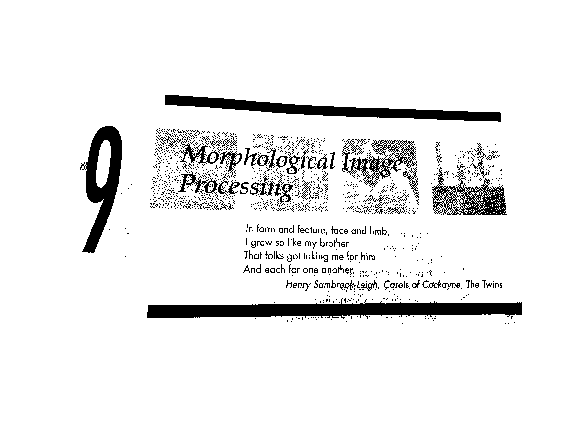

imshow(badIm)


disp("Ideal Image")

Ideal Image


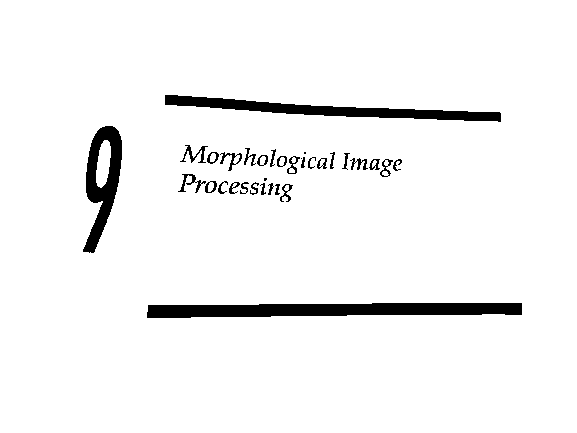

imshow(idealIm)


disp("Eroded Dilated Image with ones(3)")

Eroded Dilated Image with ones(3)


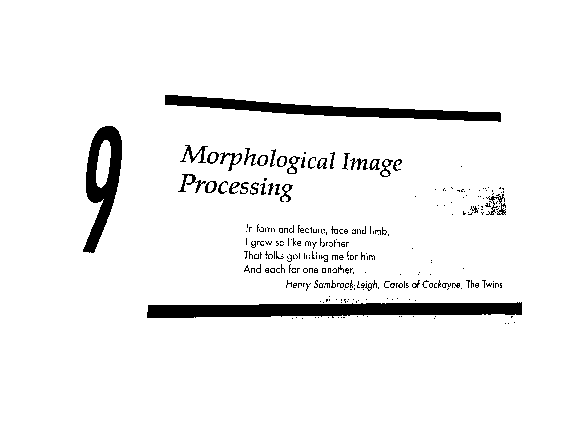

imshow(closingSe3Im)

Combination of dilation and erosion results in fewer bad pixel than the minimum value from approach 1. This tells that our result is closer to the ideal image than approach 1. Resulting image shows that objects at the center of image faded, but still have a quite visibile difference from ideal image.

se5 = ones(5)

se5 =      1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1



dilatedIm5 = imdilate(badIm, se5);
closingSe5Im = imerode(dilatedIm5, se5);
cntBadPixel = sum(sum(xor(idealIm, closingSe5Im)))

cntBadPixel = 7399


disp("Bad Image")

Bad Image


imshow(badIm)


disp("Ideal Image")

Ideal Image


imshow(idealIm)


disp("Eroded Dilated Image with ones(5)")

Eroded Dilated Image with ones(5)


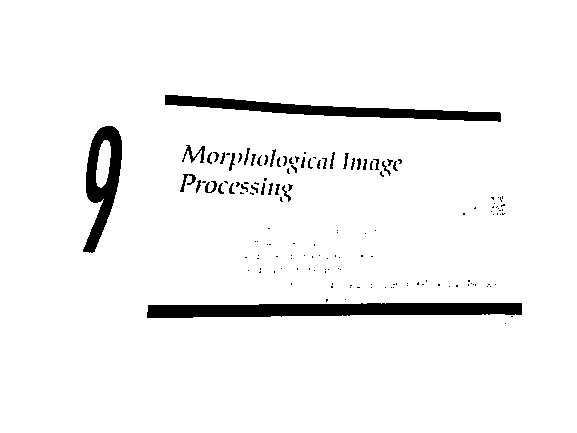

imshow(closingSe5Im)

The count of bad pixels after dilate and erode command is still tremendously lower than the minimum bad pixels after part 1 approach, but with ones(5) structure, it introduces more noises than ones(3). 

se7 = ones(7)

se7 =      1     1     1     1     1     1     1
     1     1     1     1     1     1     1
     1     1     1     1     1     1     1
     1     1     1     1     1     1     1
     1     1     1     1     1     1     1
     1     1     1     1     1     1     1
     1     1     1     1     1     1     1



dilatedIm7 = imdilate(badIm, se7);
%erodedIm = imerode(badIm, se);
closingSe7Im = imerode(dilatedIm7, se7);
cntBadPixel = sum(sum(xor(idealIm, closingSe7Im)))

cntBadPixel = 9505


disp("Bad Image")

Bad Image


imshow(badIm)


disp("Ideal Image")

Ideal Image


imshow(idealIm)


disp("Eroded Dilated Image with ones(7)")

Eroded Dilated Image with ones(7)


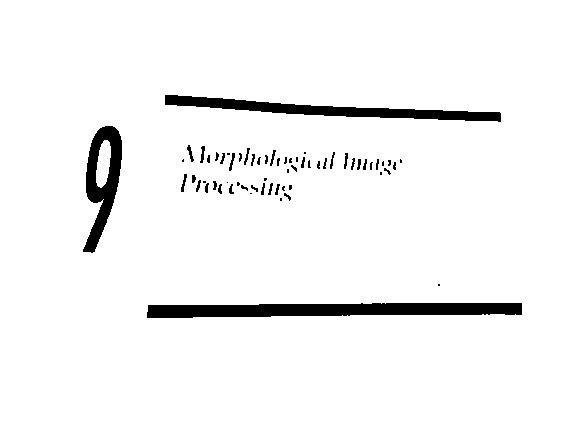

imshow(closingSe7Im)

The number of bad pixels is still lower than the minimum value from approach 1. Hower with ones(7) dimension of structuring element, we have more noises than ones(5). Objects which are needed to be kept are eroded with structuring element.

## b)

Geodesic dilation implementation:

markerIm = 1 - closingSe7Im;
maskIm = 1 - closingSe5Im;

while true
    markerImNext = imdilate(markerIm, se3) & maskIm;
    if isequal(markerIm,markerImNext)
        break;
    end
    markerIm = markerImNext;
    cntBadPixel = sum(sum(xor(idealIm, 1 - markerIm)))
    %cntBadPixel = sum(sum(xor(closingSe7Im, markerIm)))

end

cntBadPixel = 8319

cntBadPixel = 7498

cntBadPixel = 6840

cntBadPixel = 6330

cntBadPixel = 5955

cntBadPixel = 5687

cntBadPixel = 5483

cntBadPixel = 5322

cntBadPixel = 5196

cntBadPixel = 5099

cntBadPixel = 5047

cntBadPixel = 5000

cntBadPixel = 4959

cntBadPixel = 4920

cntBadPixel = 4886

cntBadPixel = 4853

cntBadPixel = 4820

cntBadPixel = 4786

cntBadPixel = 4751

cntBadPixel = 4715

cntBadPixel = 4708

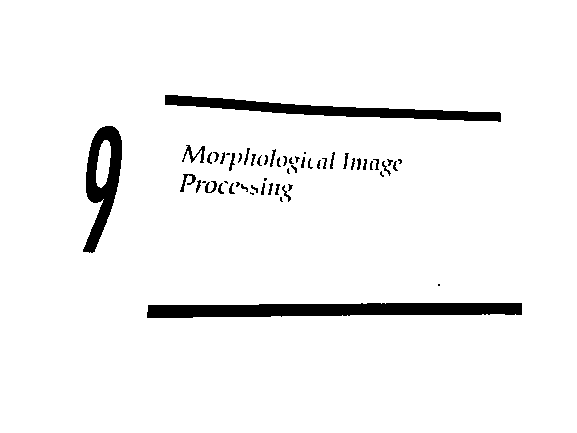


imshow(1 - markerIm)

## 3)

## a)

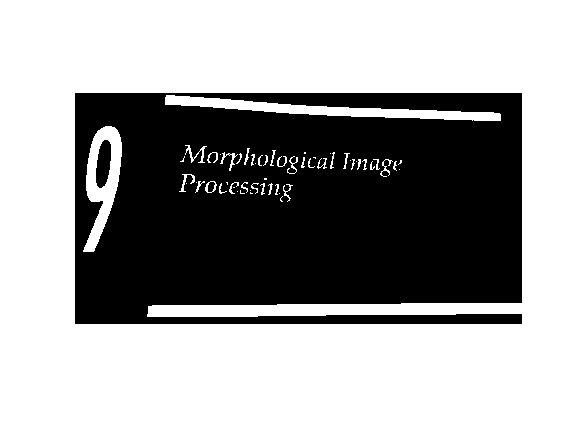

idealSkelIm = bwmorph(1 - idealIm, "skeleton");
imshow(idealSkelIm)